## LAB 3 Trajectory Control

### First task

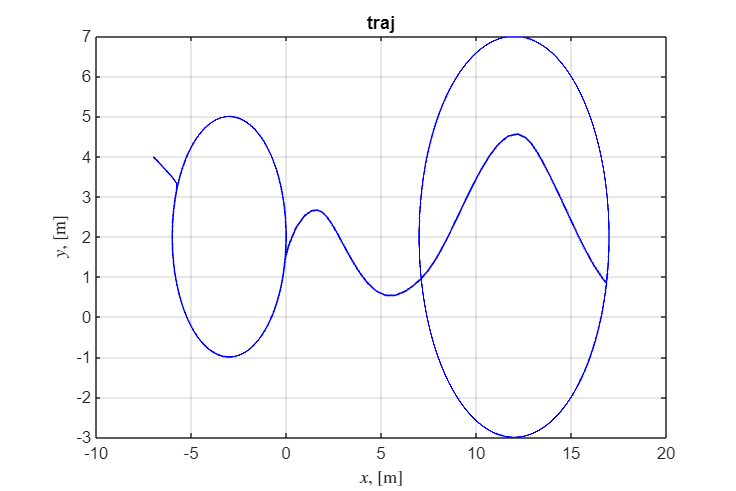

% Given
x0 = -7;
y0 = 4;
alpha0 = 3*pi/4;
m = 2.8; % in kg

% for traj
R1 = 3;
xc1 = -3;
yc1 = 2;
R3 = 5;
xc3 = 12;
yc3 = 2;

kq=3;
ke=3;

% if vs_switcher==1
% elseif vs_switcher==2
% elseif vs_switcher==3
% end

vs_switcher = 1;

vs_des = 2.5;
s_sw = [100 113.5];
Tdes=s_sw(2)+200;
warning('off');
mdlName = "first_task.slx";
sim_control = sim(mdlName,'SrcWorkspace','current');
t = sim_control.tout;
x = sim_control.simout(:,1);
y = sim_control.simout(:,2);
e = sim_control.simout(:,3);
figure('Position',[0 0 1500 1000],'units','normalized'); 
plot(x, y, ...
    'linewidth', 1,'Color','b'); grid on; hold on
xlabel('$x$, [m]','Interpreter','latex');
ylabel('$y$, [m]','Interpreter','latex');
title("traj")

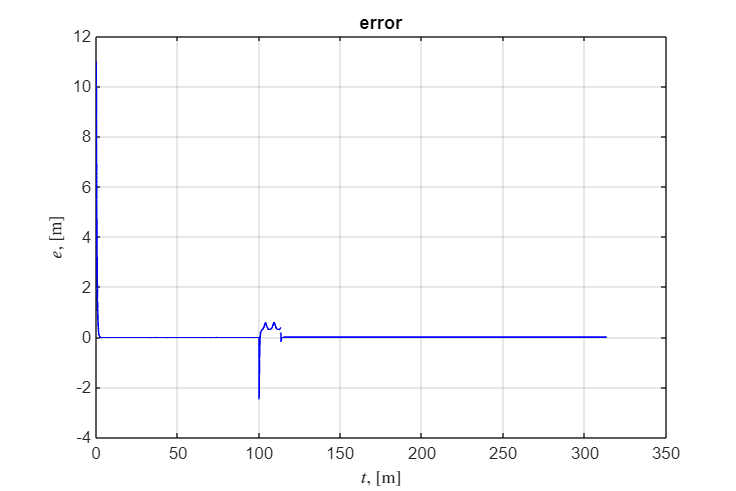

figure('Position',[0 0 1500 1000],'units','normalized'); 
plot(t, e, ...
    'linewidth', 1,'Color','b'); grid on; hold on
title("error")
% ylim([-0.1,0.1])
xlabel('$t$, [m]','Interpreter','latex');
ylabel('$e$, [m]','Interpreter','latex');

### Second task